clear all;
clc;
close all;

file_name = "bianco_3";
bag = ros2bagreader("Test_ur/" + file_name)

bag =   ros2bagreader with properties:

           FilePath: '/Users/lucabeber/Documents/Dottorato/Cubes/Test_ur/bianco_3/bianco_3_0.db3'
          StartTime: 1699281227196261794
            EndTime: 1699281263866072895
    AvailableTopics: [1×3 table]
        MessageList: [18336×3 table]
        NumMessages: 18336



bag_data = select(bag,"Topic","/data_control");
mes_data = readMessages(bag_data);

n_mess = bag_data.NumMessages;


sim_time = zeros(n_mess,1);
for i = 1:n_mess
    sim_time(i) =  mes_data{i, 1}.data(1);  
end
initial_time = sim_time(1);
sim_time(:) = sim_time(:)-initial_time;
dT = sim_time(2)

dT = 0.0020

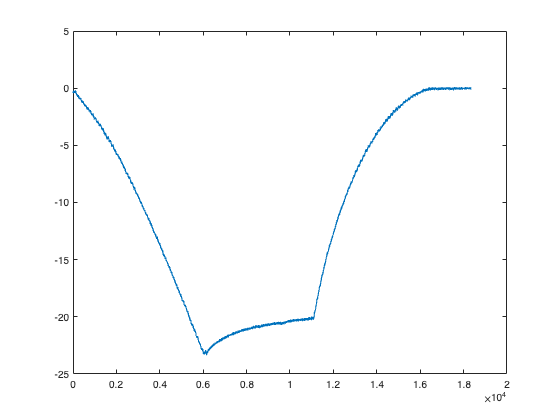


force_z = zeros(n_mess,1);
for i = 1:n_mess
    force_z(i) =  mes_data{i, 1}.data(6);  
end

plot(force_z)

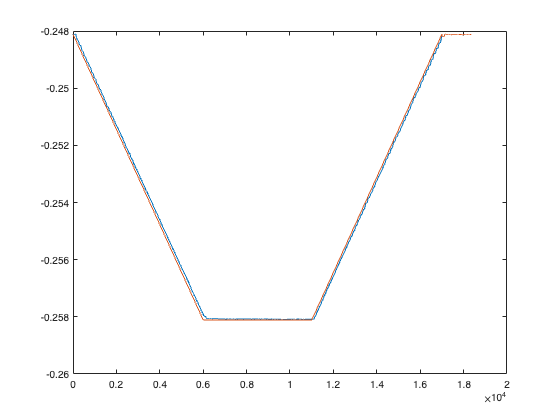


position_real = zeros(n_mess,1);
position_des = zeros(n_mess,1);
for i = 1:n_mess
    position_real(i) =  mes_data{i, 1}.data(3);  
    position_des(i) =  mes_data{i, 1}.data(2); 
end

plot([position_real,position_des])

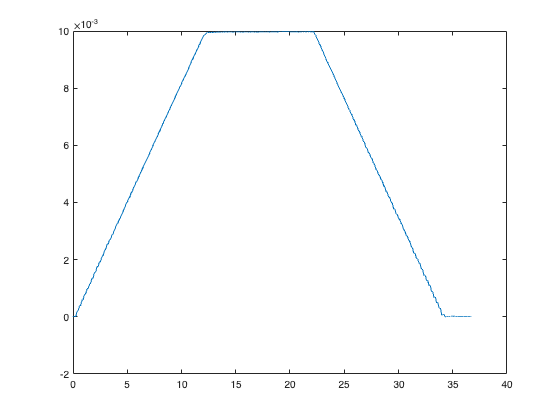

penetration = zeros(n_mess,1);
for i = 1:n_mess
    penetration(i) =  position_real(1)-position_real(i);
end

plot(sim_time(:),penetration(:))

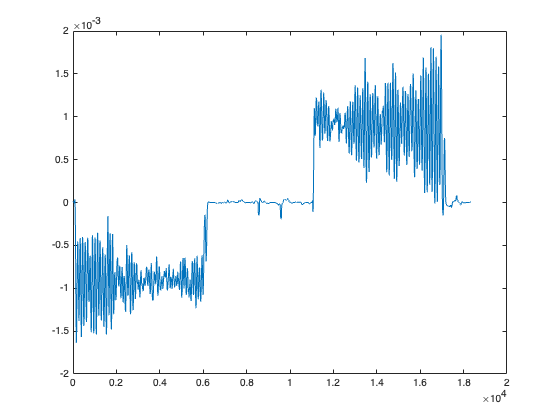

velocity_z = zeros(n_mess,1);
for i = 1:n_mess
    velocity_z(i) =  mes_data{i, 1}.data(5);  
end

plot(smoothdata(velocity_z,"SmoothingFactor",0.1))

velocity_z = smoothdata(velocity_z,"SmoothingFactor",0.1)

velocity_z =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


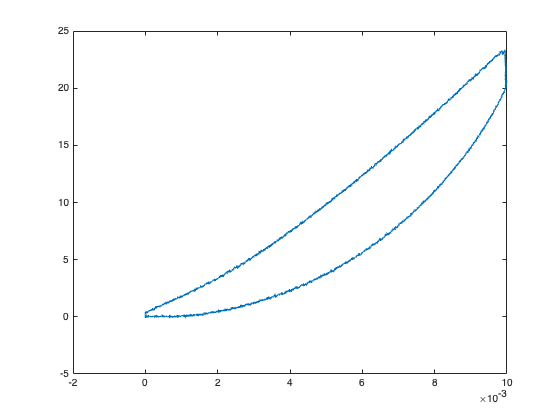

plot(penetration,-force_z)

% force_zd = zeros(n_mess,1);
% force_zd(1:n_mess-1) = diff(smoothdata(force_z,"SmoothingFactor",0.3))/(dT);
% force_zd(n_mess)=force_zd(n_mess-1);
% plot(force_zd)

% Fit the model 'z = k * u + c * up'
X = [penetration,-velocity_z];
mdl = fitlm(X, -force_z, "y~-1+x1+x2")

mdl = Linear regression model:
    y ~ x1 + x2

Estimated Coefficients:
          Estimate      SE      tStat     pValue
          ________    ______    ______    ______

    x1     1949.1      2.314    842.31      0   
    x2     2425.3     20.964    115.69      0   


Number of observations: 18336, Error degrees of freedom: 18334
Root Mean Squared Error: 2.19


% Display the regression results
%disp(mdl);
ls_coeff = lsqr(X,-force_z)

lsqr converged at iteration 2 to a solution with relative residual 0.16.


ls_coeff = 1.0e+03 *

    1.9491
    2.4253


el = ls_coeff(1)/0.05

el = 3.8981e+04

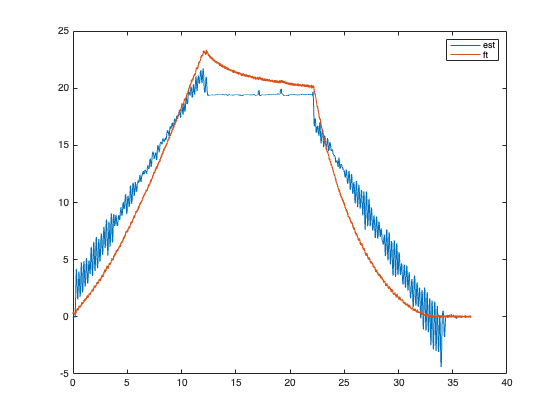


plot(sim_time,  ls_coeff(1)*X(:,1)  + ls_coeff(2)*X(:,2))
hold on 
plot(sim_time, -force_z)
hold off 
legend(["est","ft"])

% Fit the model 'z = k * u^n + c * up^n'
n = 1.5

n = 1.5000

X = real([(penetration).^(n),-velocity_z.*(penetration.^(n))]);
mdl = fitlm(X, -force_z, "y~-1+x1+x2")

mdl = Linear regression model:
    y ~ x1 + x2

Estimated Coefficients:
           Estimate       SE      tStat     pValue
          __________    ______    ______    ______

    x1         20913    13.131    1592.7      0   
    x2    4.9655e+06     22934    216.51      0   


Number of observations: 18336, Error degrees of freedom: 18334
Root Mean Squared Error: 1.17


% Display the regression results
%disp(mdl);
ls_coeff2 = lsqr(X,-force_z)

lsqr converged at iteration 2 to a solution with relative residual 0.084.


ls_coeff2 = 1.0e+06 *

    0.0209
    4.9655



% Get the coefficients 'a' and 'b' from the model
%stiffness = mdl.Coefficients.Estimate(1); % Coefficient for 'x'
% damping = mdl.Coefficients.Estimate(2); % Coefficient for 'y'
% mass = mdl.Coefficients.Estimate(3); % Coefficient for 'y'

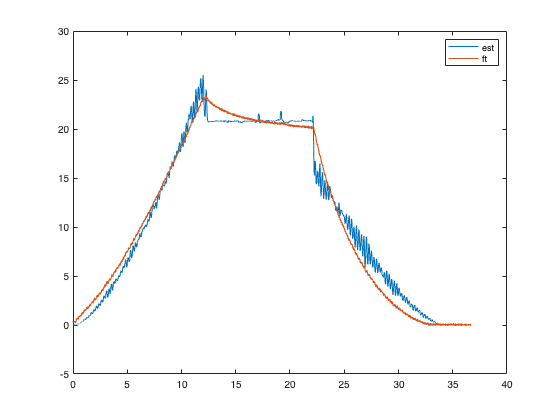


plot(sim_time,  ls_coeff2(1)*X(:,1)  + ls_coeff2(2)*X(:,2))
hold on 
plot(sim_time, -force_z)
hold off 
legend(["est","ft"])

## Elasticity and viscosity

el = 3 * ls_coeff2(1) / (4 * sqrt(0.02)) %* ( 1 - 0.7^2)% Fit the model 'z = k * u^n + c * up^n'

el = 1.1091e+05

n = 1.5

n = 1.5000

X = real([(penetration(1:3030)+0.00025).^(n),-velocity_z(1:3030).*((penetration(1:3030)+0.00025).^(n-1))]);
mdl = fitlm(X, -force_z(1:3030), "y~-1+x1")

mdl = Linear regression model:
    y ~ x1

Estimated Coefficients:
          Estimate      SE      tStat     pValue
          ________    ______    ______    ______

    x1     27431      38.137    719.28      0   


Number of observations: 3030, Error degrees of freedom: 3029
Root Mean Squared Error: 0.392


% Display the regression results
%disp(mdl);
ls_coeff3 = lsqr(X,-force_z(1:3030))

lsqr converged at iteration 2 to a solution with relative residual 0.05.


ls_coeff3 = 1.0e+04 *

    2.4077
    1.4155


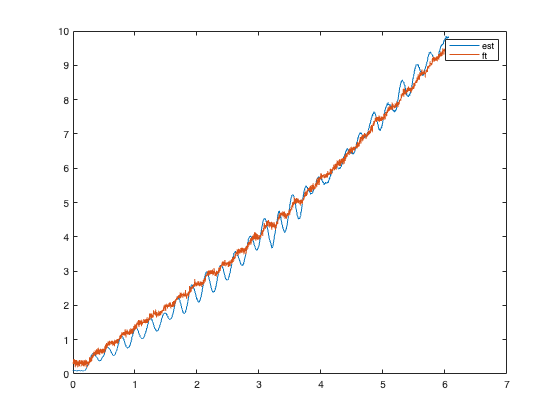

plot(sim_time(1:3030),  ls_coeff3(1)*X(:,1) + ls_coeff3(2)*X(:,2))
hold on 
plot(sim_time(1:3030), -force_z(1:3030))
hold off 
legend(["est","ft"])

el = 3 * ls_coeff3(1) / (4 * sqrt(0.02))

el = 1.2769e+05

ft = fittype('a + b*exp(-1/c*x) + d * exp(-1/e*x)');
f = fit(sim_time(6210:11000)-12.42,-force_z(6210:11000),'exp2')%,ft,"Lower",[0,0,0],"StartPoint",[1,1,1,1,1])

f =      General model Exp2:
     f(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =       1.647  (1.629, 1.666)
       b =     -0.5604  (-0.5718, -0.5489)
       c =       21.33  (21.31, 21.35)
       d =   -0.006061  (-0.006176, -0.005947)

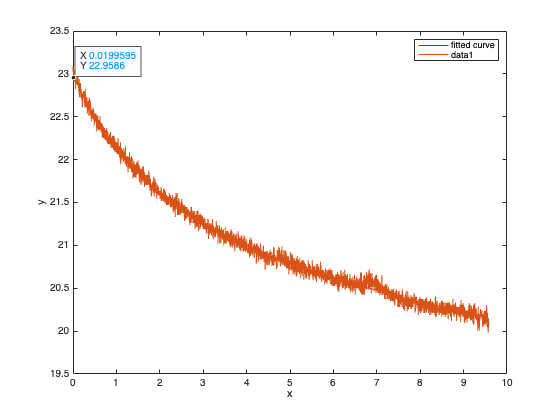

plot(f)
hold on 
plot(sim_time(6210:11000)-12.42,-force_z(6210:11000))
hold off

tr = 12.2

tr = 12.2000

hmax = 0.01

hmax = 0.0100

tau1 = 1/-f.b

tau1 = 1.7846

beta1 = tau1/tr*(exp(-tr/tau1)-1)

beta1 = -0.1461

c1 = f.a /(beta1 * hmax * (8*sqrt(0.01)/3))

c1 = -4.2280e+03


tau2 = 1/-f.d

tau2 = 164.9800

beta2 = tau2/tr*(exp(-tr/tau2)-1)

beta2 = -0.9639

c2 = f.c /(beta2 * hmax * (8*sqrt(0.01)/3))

c2 = -8.2978e+03

el2 = -c1-c2

el2 = 1.2526e+04

ft = fittype('a + b*exp(-1/c*x) + d * exp(-1/e*x) + f * exp(-1/g*x)');
f = fit(sim_time(6210:11000)-12.42,-force_z(6210:11000),'exp2')

f =      General model Exp2:
     f(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =       1.647  (1.629, 1.666)
       b =     -0.5604  (-0.5718, -0.5489)
       c =       21.33  (21.31, 21.35)
       d =   -0.006061  (-0.006176, -0.005947)

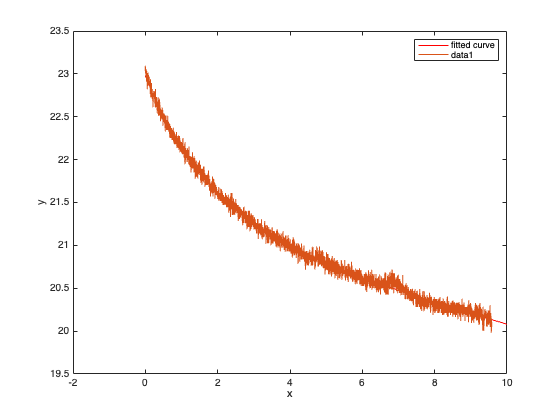

plot(f)
hold on 
plot(sim_time(6210:11000)-12.42,-force_z(6210:11000))
hold off

tr = 12.2

tr = 12.2000

hmax = 0.01

hmax = 0.0100

tau1 = f.b

tau1 = -0.5604

beta1 = tau1/tr*(exp(-tr/tau1)-1)

beta1 = -1.3108e+08

c1 = f.a /(beta1 * hmax * (8*sqrt(0.01)/3))

c1 = -4.7131e-06


tau2 = 1/-f.d

tau2 = 164.9800

beta2 = tau2/tr*(exp(-tr/tau2)-1)

beta2 = -0.9639

c2 = f.c /(beta2 * hmax * (8*sqrt(0.01)/3))

c2 = -8.2978e+03

el2 = -c1-c2

el2 = 8.2978e+03